% DEMO_FOURDOF_LOBPCG
%   Runs the 4-DOF LOBPCG example and prints diagnostics.

clear; clc;

problem = 2; %1 = 4DOF spring, 2 =) 1000DOF Spring, 3 = testingEIFEM matrices

solver = Testing_LOBPCG(problem);

% Solver Controls:
solver.b      = 4;        % number of modes
solver.use_precond = true;
solver.use_physical_x = true; % feed aproximation to eigenvaluees (simulating coarse from superelement) as starting point
solver.tol    = 1e-6;    % residual tolerance
solver.maxit  = 20000;       % max iterations
solver.verbose = false;

results = solver.run_demo();

  Converged: all residuals < rel tol.
Elapsed time is 10.733455 seconds.




 

% solver2 = Testing_LOBPCG(problem);
% 
% % Solver Controls:
% solver2.b      = 4;        % number of modes
% solver2.use_precond = true;
% solver2.tol    = 1e-6;    % residual tolerance
% solver2.maxit  = 20000;       % max iterations
% solver2.verbose = false;
% solver2.use_physical_x = false;
% results2 = solver2.run_demo();

  Converged: all residuals < rel tol.
Elapsed time is 13.555307 seconds.


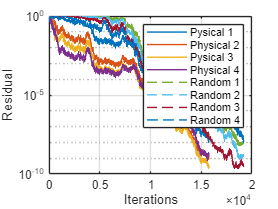

% figure
% x_axis = 1:length(results.history.rnorms);
% for i = 1:solver.b
%     semilogy(x_axis, results.history.rnorms(:,i), 'LineWidth', 1)
%     hold on
% end
% xlabel('Iterations')
% ylabel('Residual')
% grid on
% 
% x_axis = 1:length(results2.history.rnorms);
% for i = 1:solver2.b
%     semilogy(x_axis, results2.history.rnorms(:,i), 'LineWidth', 1,'LineStyle','--')
% end
% legend('Pysical 1','Physical 2','Pysical 3','Physical 4','Random 1','Random 2','Random 3','Random 4')